% [V,score,s2] = pca(X)

V =     0.0087
    0.0062
    0.0099
    0.0155
    0.0138
    0.0123
    0.0124
    0.0050
    0.0109
    0.0117


score =    71.4397
  -71.4397


s2 = 1.0207e+04

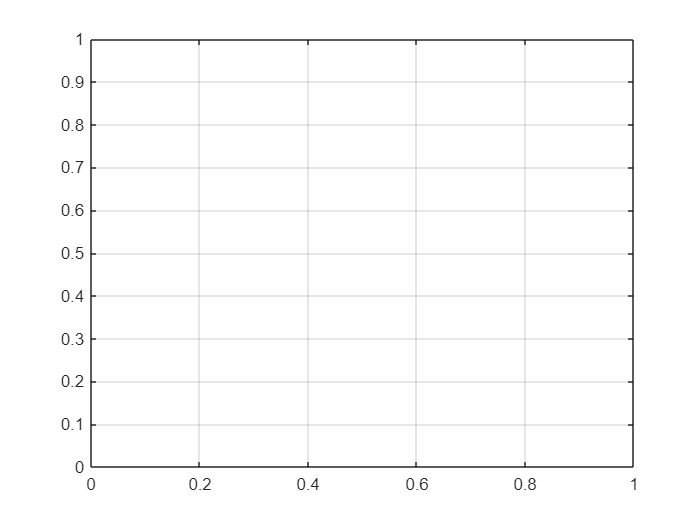

hold on, box on, grid on

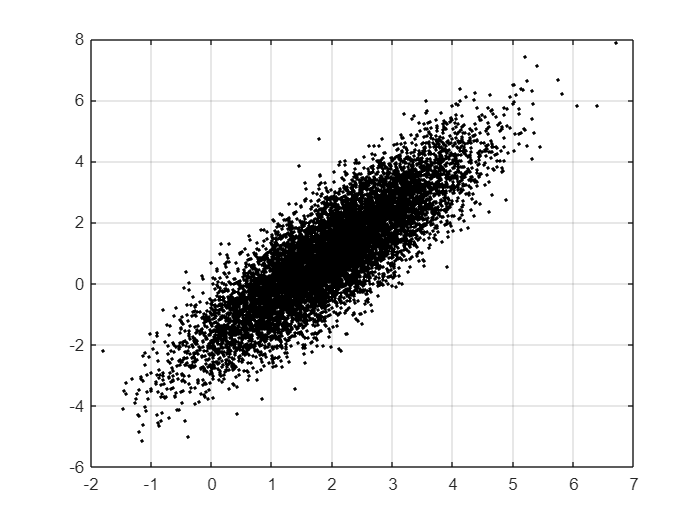

xC = [2; 1;]; % Center of data (mean)
sig = [2; .5;]; % Principal axes
theta = pi/3; % Rotate cloud by pi/3
R = [cos(theta) -sin(theta); % Rotation matrix
sin(theta) cos(theta)];
nPoints = 10000; % Create 10,000 points
X = R*diag(sig)*randn(2,nPoints) + diag(xC)*ones(2,nPoints);
scatter(X(1,:),X(2,:),'k.','LineWidth',2)

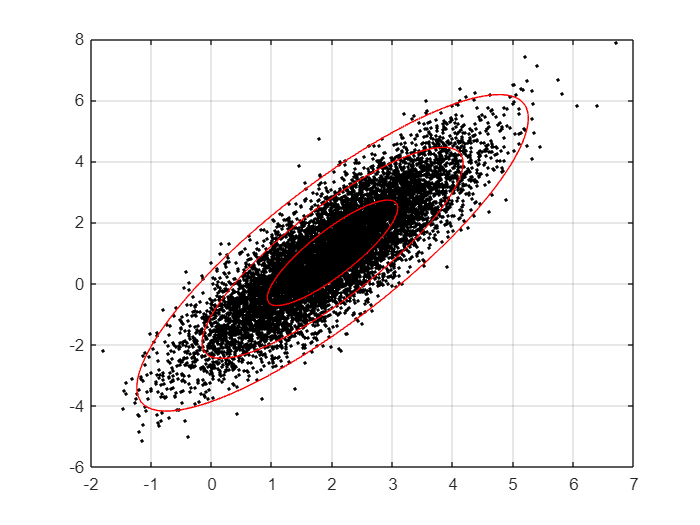

Xavg = mean(X,2); % Compute mean
B = X - Xavg*ones(1,nPoints); % Mean-subtracted Data
[U,S,V] = svd(B/sqrt(nPoints),'econ'); % PCA via SVD
scatter(X(1,:),X(2,:),'k.','LineWidth',2) % Plot data
theta = (0:.01:1)*2*pi;
Xstd = U*S*[cos(theta); sin(theta)]; % 1-std conf. interval
plot(Xavg(1)+Xstd(1,:),Xavg(2) + Xstd(2,:),'r-')
plot(Xavg(1)+2*Xstd(1,:),Xavg(2) + 2*Xstd(2,:),'r-')
plot(Xavg(1)+3*Xstd(1,:),Xavg(2) + 3*Xstd(2,:),'r-')

% [V,score,s2] = pca(X);
% norm(V*score' - B)
